## Laplace central DQ

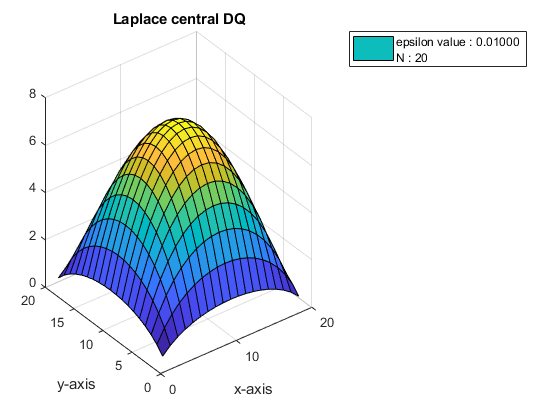

clc;
clear all;

Grid = UnitGrid(20);
epsilon = 10^(-2);

n = Grid.n;
f = ones((n-1)^2,1);
BC = @(x,y) 0;

Grid.setBoundryCondtion("Bup",BC);
Grid.setBoundryCondtion("Bdown",BC);
Grid.setBoundryCondtion("Bleft",BC);
Grid.setBoundryCondtion("Bright",BC);


[A_laplace,b_laplace] = laplace(Grid,f,epsilon);
x = A_laplace\(f+b_laplace);
u = reshape(x,n-1,n-1);
surf(u);
epsilonstr = sprintf(['epsilon value : %.5f \n' ...
    'N : %.f'],epsilon,n);
legend(epsilonstr);
xlabel('x-axis');
ylabel('y-axis');
title('Laplace central DQ');

## Laplace + Diffusion central DQ

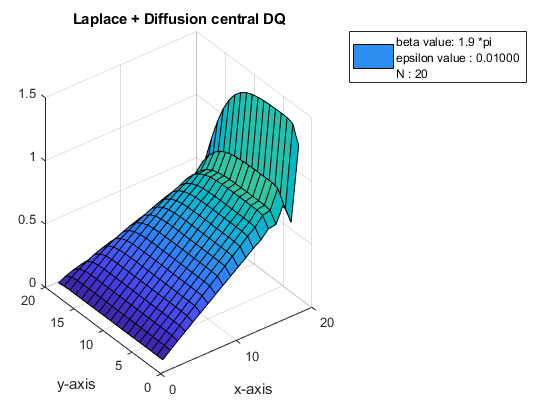

beta = 0.6  *pi;
[A_diff,b_diff] = diffusion(Grid,beta);
x = (A_laplace + A_diff)\(f +b_laplace+b_diff);
u = reshape(x,n-1,n-1);
surf(u);

str = sprintf(['beta value: %.1f *pi  \n' ...
    'epsilon value : %.5f \n' ...
    'N : %.f'],beta,epsilon,n);
legend(str);
xlabel('x-axis');
ylabel('y-axis');

title('Laplace + Diffusion central DQ')

## Laplace + Diffusion Upwind DQ

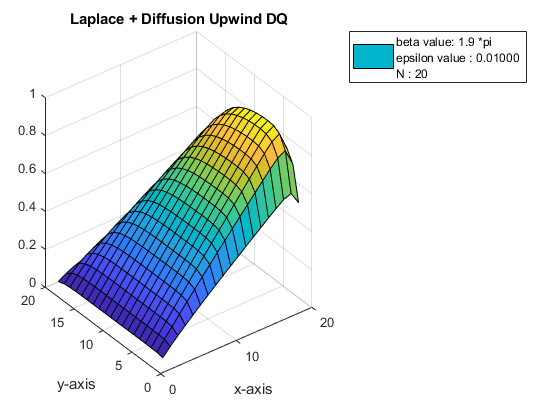

[A_diff,b_diff] = diffusionUpwind(Grid,beta);
x = (A_laplace + A_diff)\(f +b_laplace+b_diff);
u = reshape(x,n-1,n-1);
surf(u);

epsilonstr = sprintf('epsilon value : %.5f',epsilon);
legend(epsilonstr);

str = sprintf(['beta value: %.1f *pi  \n' ...
    'epsilon value : %.5f \n' ...
    'N : %.f'],beta,epsilon,n);
legend(str);
xlabel('x-axis');
ylabel('y-axis');

title('Laplace + Diffusion Upwind DQ')

## Bonusaufgabe

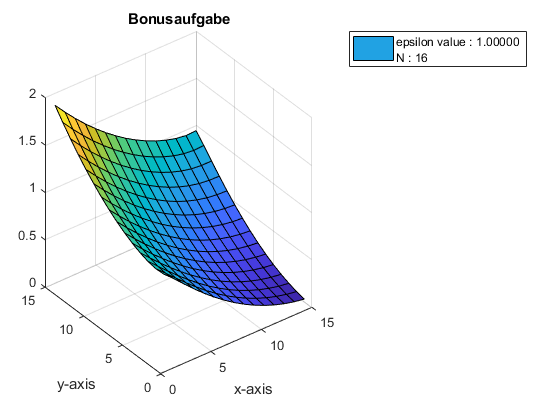

epsilon = 1;
Grid = UnitGrid(16);
n = Grid.n;


f = -4*ones((n-1)^2,1);
BC = @(x,y) x^2 + y^2;


Grid.setBoundryCondtion("Bup",BC);
Grid.setBoundryCondtion("Bdown",BC);
Grid.setBoundryCondtion("Bleft",BC);
Grid.setBoundryCondtion("Bright",BC);

[A_laplace,b_laplace] = laplace(Grid,f,epsilon);
x = A_laplace\(f+b_laplace);
u = reshape(x,n-1,n-1);
surf(u);
epsilonstr = sprintf(['epsilon value : %.5f \n' ...
    'N : %.f'],epsilon,n);
legend(epsilonstr);
xlabel('x-axis');
ylabel('y-axis');
title('Bonusaufgabe');